# Assignment 2: Task 2

## Load experiment data

if (~exist("session2","var"))
    load("group-01.02.mat");
end

f = session2.task2.frequency;
R0 = session2.task2.antennas_distance;
H = session2.task2.reflection_height;
epsilon1 = 8.854e-12;

## Free space

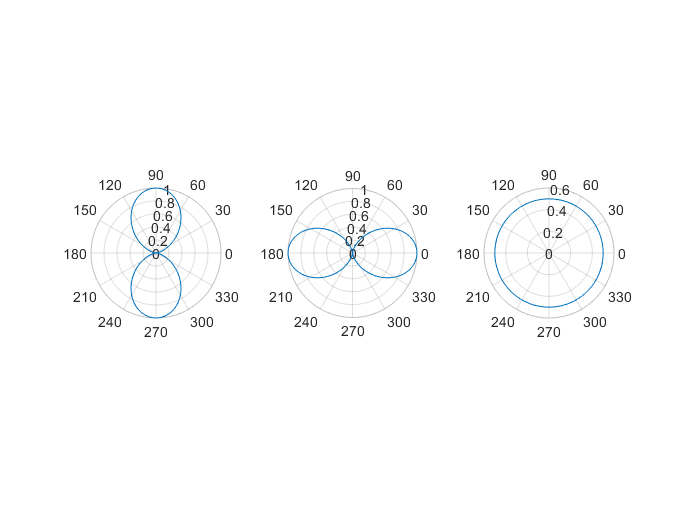

epsilon2 = epsilon1;

figure
% Vertical
tau = 0;
phi = 0.5*pi;
subplot(1,3,1,polaraxes)
angular_pattern(f,R0,H(1),tau,phi,epsilon1,epsilon2)
% Horizontal
tau = 0;
phi = 0.0*pi;
subplot(1,3,2,polaraxes)
angular_pattern(f,R0,H(1),tau,phi,epsilon1,epsilon2)
% Circular
tau = 0.25*pi;
phi = 0.0*pi;
subplot(1,3,3,polaraxes)
angular_pattern(f,R0,H(1),tau,phi,epsilon1,epsilon2)

## Metallic plate

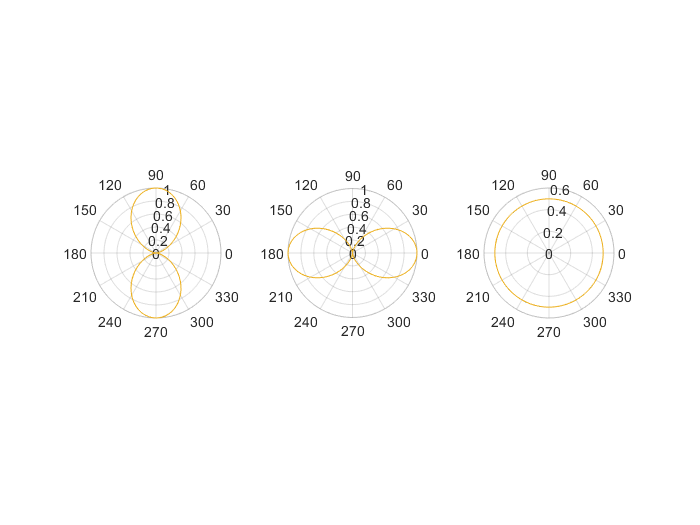

epsilon2 = -1e10j * epsilon1;

figure
% Vertical
tau = 0;
phi = 0.5*pi;
subplot(1,3,1,polaraxes)
angular_pattern(f,R0,H(1),tau,phi,epsilon1,epsilon2)
hold on
angular_pattern(f,R0,H(2),tau,phi,epsilon1,epsilon2)
angular_pattern(f,R0,H(3),tau,phi,epsilon1,epsilon2)
% legend({['H = ',num2str(H(1)),' [m]'],['H = ',num2str(H(2)),' [m]'],['H = ',num2str(H(3)),' [m]']})
hold off
% Horizontal
tau = 0;
phi = 0.0*pi;
subplot(1,3,2,polaraxes)
angular_pattern(f,R0,H(1),tau,phi,epsilon1,epsilon2)
hold on
angular_pattern(f,R0,H(2),tau,phi,epsilon1,epsilon2)
angular_pattern(f,R0,H(3),tau,phi,epsilon1,epsilon2)
% legend({['H = ',num2str(H(1)),' [m]'],['H = ',num2str(H(2)),' [m]'],['H = ',num2str(H(3)),' [m]']})
hold off
% Circular
tau = 0.25*pi;
phi = 0.0*pi;
subplot(1,3,3,polaraxes)
angular_pattern(f,R0,H(1),tau,phi,epsilon1,epsilon2)
hold on
angular_pattern(f,R0,H(2),tau,phi,epsilon1,epsilon2)
angular_pattern(f,R0,H(3),tau,phi,epsilon1,epsilon2)
% legend({['H = ',num2str(H(1)),' [m]'],['H = ',num2str(H(2)),' [m]'],['H = ',num2str(H(3)),' [m]']})
hold off

## Dielectric Plate

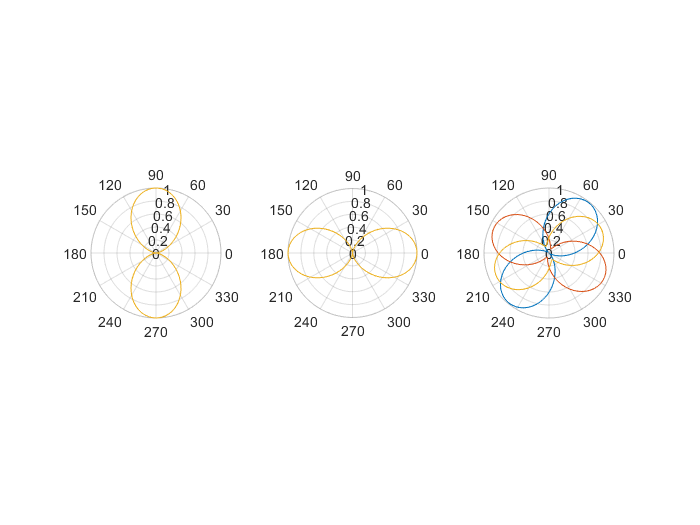

epsilon2 = session2.task2.dielectric_prermittivity; epsilon2 = epsilon2 * 8.8541878128e-12;

figure
% Vertical
tau = 0;
phi = 0.5*pi;
subplot(1,3,1,polaraxes)
angular_pattern(f,R0,H(1),tau,phi,epsilon1,epsilon2)
hold on
angular_pattern(f,R0,H(2),tau,phi,epsilon1,epsilon2)
angular_pattern(f,R0,H(3),tau,phi,epsilon1,epsilon2)
% legend({['H = ',num2str(H(1)),' [m]'],['H = ',num2str(H(2)),' [m]'],['H = ',num2str(H(3)),' [m]']})
hold off
% Horizontal
tau = 0;
phi = 0.0*pi;
subplot(1,3,2,polaraxes)
angular_pattern(f,R0,H(1),tau,phi,epsilon1,epsilon2)
hold on
angular_pattern(f,R0,H(2),tau,phi,epsilon1,epsilon2)
angular_pattern(f,R0,H(3),tau,phi,epsilon1,epsilon2)
% legend({['H = ',num2str(H(1)),' [m]'],['H = ',num2str(H(2)),' [m]'],['H = ',num2str(H(3)),' [m]']})
hold off
% Circular
tau = 0.25*pi;
phi = 0.0*pi;
subplot(1,3,3,polaraxes)
angular_pattern(f,R0,H(1),tau,phi,epsilon1,epsilon2)
hold on
angular_pattern(f,R0,H(2),tau,phi,epsilon1,epsilon2)
angular_pattern(f,R0,H(3),tau,phi,epsilon1,epsilon2)
% legend({['H = ',num2str(H(1)),' [m]'],['H = ',num2str(H(2)),' [m]'],['H = ',num2str(H(3)),' [m]']})
hold off

% Tilted linear
% phi = 0.2*pi;
% tau = 0*pi;
% subplot(1,4,4,polaraxes)
% angular_pattern(f,R0,H(1),tau,phi,epsilon1,epsilon2)
% hold on
% angular_pattern(f,R0,H(2),tau,phi,epsilon1,epsilon2)
% angular_pattern(f,R0,H(3),tau,phi,epsilon1,epsilon2)
% % legend({['H = ',num2str(H(1)),' [m]'],['H = ',num2str(H(2)),' [m]'],['H = ',num2str(H(3)),' [m]']})
% hold off

## Received wave at Brewster's angle

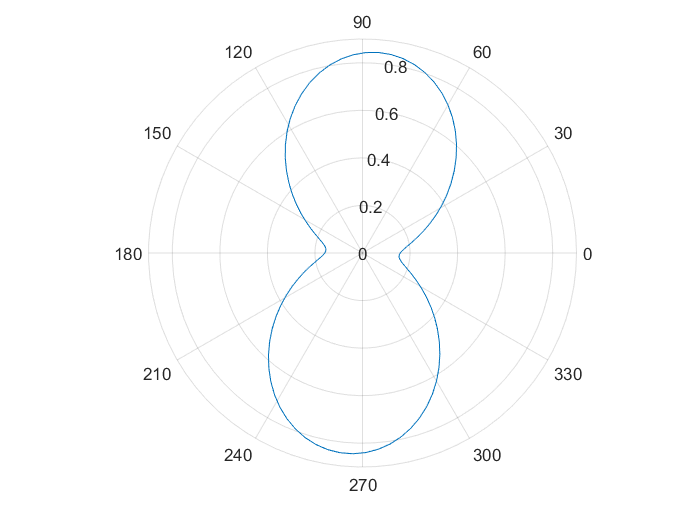

epsilon2 = session2.task2.dielectric_prermittivity; epsilon2 = epsilon2 * 8.8541878128e-12;

tau = 0.25*pi;
phi = 0.0*pi;

angle_b = plot_brewster(epsilon1,epsilon2,'off');

H_b = tan(0.5*pi - angle_b)*R0*0.5;

figure
angular_pattern(f,R0,H_b,tau,phi,epsilon1,epsilon2)